# Test eFlux

This notebook tests components of the eFlux algorithm.

## Simulate weights from normal distribution

First, let's examine the distribution of weights as a function of Z-score and p-values from a normal distribution.

x = normrnd(0, 1, [1,100])

x =     1.9085    0.1222    1.0470   -0.2269   -0.1625    0.6901    0.5558   -1.1203   -1.5327   -1.0979   -1.4158    0.0596   -0.4113   -0.3680   -1.3610    0.7796    0.4394   -0.0896    1.0212   -0.8740    0.4147    0.3484    0.3493   -0.7292    0.3268   -0.5149   -0.8964   -1.2033    1.0378   -0.8459   -0.1729   -1.2087   -0.2971   -3.2320   -1.0870   -1.4264   -1.0145   -0.2133   -0.3253    1.9444   -0.5718   -0.2500   -1.5693   -0.4774   -1.3380    0.0303    0.8531    0.4043   -0.7006   -1.6305


pvalues = zeros([1, 100]);
zscores = zeros([1, 100]);
for i = 1:length(x)   
    [~, pvalues(i), ~, zscores(i)] = ztest(x(i), 0, 1);
end

zscores

zscores =     1.9085    0.1222    1.0470   -0.2269   -0.1625    0.6901    0.5558   -1.1203   -1.5327   -1.0979   -1.4158    0.0596   -0.4113   -0.3680   -1.3610    0.7796    0.4394   -0.0896    1.0212   -0.8740    0.4147    0.3484    0.3493   -0.7292    0.3268   -0.5149   -0.8964   -1.2033    1.0378   -0.8459   -0.1729   -1.2087   -0.2971   -3.2320   -1.0870   -1.4264   -1.0145   -0.2133   -0.3253    1.9444   -0.5718   -0.2500   -1.5693   -0.4774   -1.3380    0.0303    0.8531    0.4043   -0.7006   -1.6305


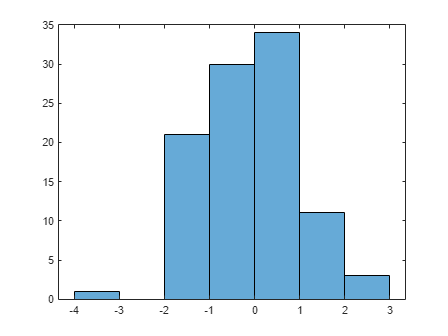

histogram(zscores)

pvalues

pvalues =     0.0563    0.9027    0.2951    0.8205    0.8709    0.4902    0.5784    0.2626    0.1254    0.2723    0.1568    0.9525    0.6809    0.7129    0.1735    0.4356    0.6604    0.9286    0.3072    0.3821    0.6784    0.7275    0.7269    0.4659    0.7438    0.6066    0.3700    0.2289    0.2994    0.3976    0.8627    0.2268    0.7664    0.0012    0.2771    0.1537    0.3104    0.8311    0.7449    0.0518    0.5675    0.8026    0.1166    0.6331    0.1809    0.9758    0.3936    0.6860    0.4835    0.1030


w = zeros([1, 100]);
epsilon = 1e-3;
for i = 1:length(x)
    w(i) = calculateWeight(zscores(i), pvalues(i), epsilon);
end

w

w =     1.8520    0.0629    0.7891    0.8421    0.8454    0.4028    0.2853    0.7092    0.6217    0.7139    0.6465    0.0538    0.8270    0.8312    0.6583    0.4910    0.2002    0.8478    0.7585    0.7580    0.1844    0.1459    0.1464    0.7835    0.1347    0.8150    0.7538    0.6919    0.7781    0.7631    0.8449    0.6907    0.8373    0.3100    0.7161    0.6443    0.7308    0.8429    0.8350    1.8946    0.8075    0.8406    0.6139    0.8196    0.6632    0.0517    0.5683    0.1779    0.7881    0.6011


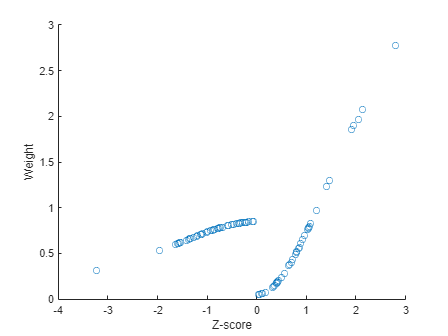

scatter(zscores, w)
xlabel('Z-score')
ylabel('Weight')

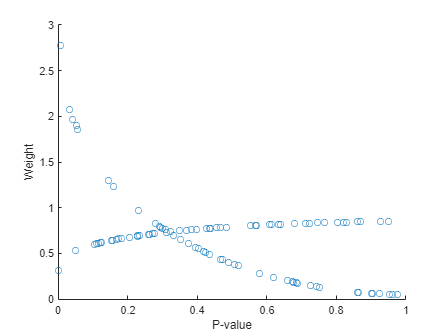

scatter(pvalues, w)
xlabel('P-value')
ylabel('Weight')

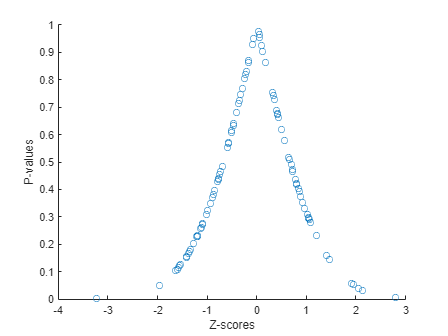

scatter(zscores, pvalues)
xlabel('Z-scores')
ylabel('P-values')

y = tan(x)

y =    -2.8476    0.1228    1.7314   -0.2309   -0.1639    0.8254    0.6211   -2.0673  -26.2317   -1.9544   -6.3989    0.0596   -0.4361   -0.3856   -4.6955    0.9884    0.4701   -0.0899    1.6324   -1.1949    0.4402    0.3633    0.3642   -0.8936    0.3390   -0.5658   -1.2510   -2.5973    1.6951   -1.1291   -0.1747   -2.6395   -0.3062   -0.0907   -1.9030   -6.8789   -1.6081   -0.2166   -0.3373   -2.5509   -0.6435   -0.2554 -675.2844   -0.5173   -4.2173    0.0303    1.1454    0.4278   -0.8433   16.7174


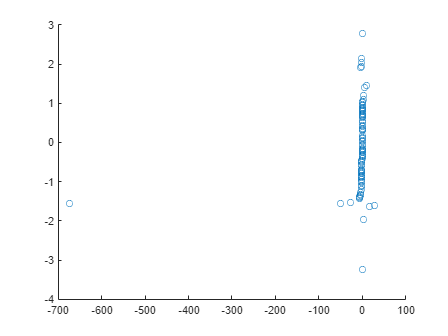

scatter(y, x)